**INFORME TALLER 11**

** MATLAB**

**DIANA CAROLINA PINZÓN MOLINA**

**OLGA LUCIA QUINTERO MONTOYA**

DOCENTE

**UNIVERSIDAD EAFIT**

**ECUACIONES DIFERENCIALES**

**MEDELLÍN**

**2023-2**

## Invasión zombie

**Introducción**

*El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función ode45 de MATLAB, la ecuación de estado de un modelo epidemiológico SIRV (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.*

El modelo epidemiológico SIRV es una extensión del modelo epidemiológico básico SIR (Susceptible-Infectado-Recuperado) que incluye una categoría adicional de individuos, "V" para Vacunados. Este modelo es utilizado para simular y comprender la propagación de enfermedades infecciosas en una población, considerando la interacción entre individuos susceptibles, infectados, recuperados y vacunados.

**Metodología**

Resolver los ejercicios dispuestos por medio del software de MATLAB y sus comandos, usando  métodos explicados en clase, además, cambiando algunas variables para poder comparar y probar diferentes ecuaciones con cambios evidentes debido a sus condiciones iniciales. Se espera poder también graficar las soluciones y llegar a conclusiones en base a estas.

**Descripción del modelo**

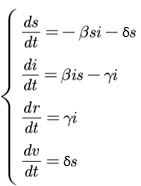

Supuestos: población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, *s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad), *i* es el porcentaje de personas infectadas, *r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y *v* es el porcentaje de personas vacunadas.

β es la tasa de transmisión, γ es la tasa de recuperación y aislamiento, y δ es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): β = 0.1, γ = 0.02, δ = 0.001, *s*(0) = 0.8, *i*(0) = 0.1, *r*(0) = 0, *v*(0) = 0.1

**Se hicieron las verificaciones con Ro y se hayo que da igual a 4 lo que nos dice que si hay pandemia **

Para el desarrollo de este taller al hablar de infectados se va a hacer alucion a los zombies, como si se estuviera estudiando un modelo de una invasión zombie.

**Desarrollo**

1. Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

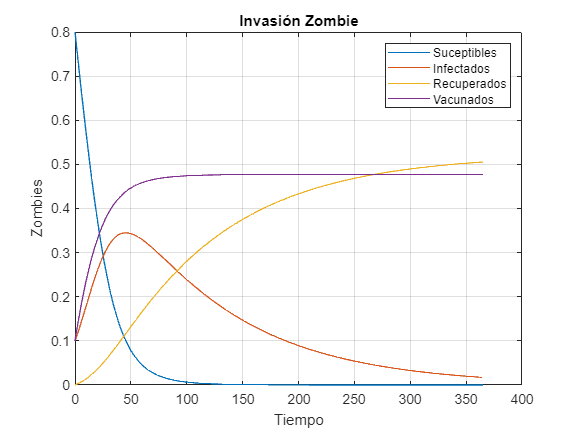

%taller 11 modelo epidemiologico


%defino variables de estado
syms S(t) I(t) R(t) V(t)

%defino constantes

%tasa de trasnmisión
Beta = 0.1;
%tasa vacunacion
Gamma = 0.01;
%tasa recuperacion
Delta = 0.02;

%defino ecuciones de estado para la invasion zombie

%suceptibles xombie
dSZombies = diff(S(t),t,1);

%infectados zombies
dIZombies = diff(I(t),t,1);

%recuperacion zombies
dRZombies = diff(R(t),t,1);

%vacunados zombies
dVZombies = diff(V(t),t,1);

%espacio de solucion temporal
%tiempo de muestre para la invasion Zombie en un dia
Ts = 1;
%vamos a trabajr 1 año
tmin = 0;
tmax = 365;
% construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;

%Condiciones iniciales
Ci_SZ = 0.8;
Ci_IZ = 0.1;
Ci_RZ = 0;
Ci_VZ = 0.1;
%
%como vamos a resolver numericamente armamos el vector con ci
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies = -Beta*S*I-Delta*S;
Tasa_IZombies = Beta*I*S-Gamma*I;
Tasa_RZombies = Gamma*I;
Tasa_VZombies = Delta*S;
% Solucion Numerica
%Resolver usando el comando ODE45
Funciones_estado = odeFunction ([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies], [S I R V]);
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_Zombies);
%graficamos solución
figure 
plot(tiempo,Salida);
title('Invasión Zombie');
xlabel('Tiempo');
ylabel('Zombies');
grid on;
legend('Suceptibles','Infectados','Recuperados','Vacunados');

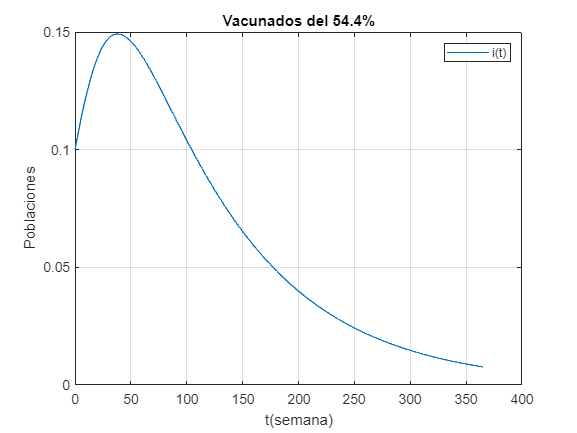

%cambiamos condiciones iniciales cuidando de su suma de 1
ci = [0.356 0.1 0 0.544]; 
%usamos ODE45 para solucionar
[tiempo,Salida] = ode45(Funciones_estado,tspan,ci);

%graficamos
figure
plot(tiempo,Salida(:,2))
title('Vacunados del 54.4%')
xlabel('t(semana)')
ylabel('Poblaciones')
grid,
legend('i(t)')

2.Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

*1ia = 0.15*

*2ib = 0.20*

*3ic = 0.25*

*4id = 0.01*

*5ie = 0.7*

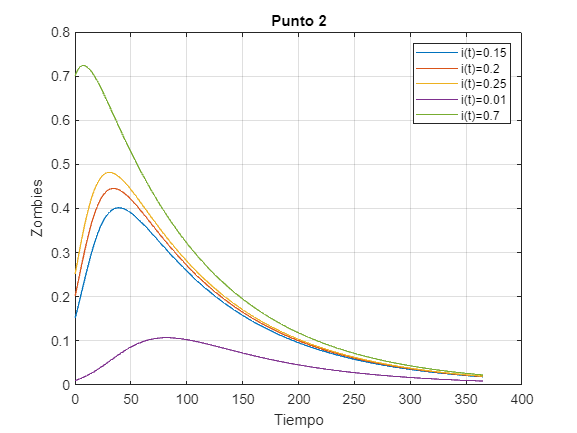

% Cambiamos condiciones iniciales de los afectados zombies teniendo en
% cuenta que se mantenga en 1 el valor total de las ci y dejando constantes
% los vacunados

% CASO a
% Vector de ci para resolver numericamente 
Ci2a = [0.75 0.15 0 0.1];

% Usamos el comando ODE445 para resolver
Funciones_estado2a = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S  I R V]);

% Resolver usando comando ODE 45
[tiempo2a,Salida2a] = ode45(Funciones_estado2a,tspan,Ci2a);

% CASO b
Ci2b_SZ = 0.70;
Ci2b_IZ = 0.20;
Ci2b_RZ = 0;
Ci2b_SVZ = 0.1;

% Vector de ci para resolver numericamente 
Ci2b_Zombies = [Ci2b_SZ Ci2b_IZ Ci2b_RZ Ci2b_SVZ];
% Usamos el comando ODE445 para resolver
Funciones_estado2b = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo2b,Salida2b] = ode45(Funciones_estado2b,tspan,Ci2b_Zombies);

% CASO c
Ci2c_SZ = 0.65;
Ci2c_IZ = 0.25;
Ci2c_RZ = 0;
Ci2c_SVZ = 0.1;

% Vector de ci para resolver numericamente 
Ci2c_Zombies = [Ci2c_SZ Ci2c_IZ Ci2c_RZ Ci2c_SVZ];
% Usamos el comando ODE445 para resolver
Funciones_estado2c = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo2c,Salida2c] = ode45(Funciones_estado2c,tspan,Ci2c_Zombies);

% CASO d
Ci2d_SZ = 0.89;
Ci2d_IZ = 0.01;
Ci2d_RZ = 0;
Ci2d_SVZ = 0.1;

% Vector de ci para resolver numericamente 
Ci2d_Zombies = [Ci2d_SZ Ci2d_IZ Ci2d_RZ Ci2d_SVZ];
% Usamos el comando ODE445 para resolver
Funciones_estado2d = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo2d,Salida2d] = ode45(Funciones_estado2d,tspan,Ci2d_Zombies);

% CASO e
Ci2e_SZ = 0.2;
Ci2e_IZ = 0.7;
Ci2e_RZ = 0;
Ci2e_SVZ = 0.1;

% Vector de ci para resolver numericamente 
Ci2e_Zombies = [Ci2e_SZ Ci2e_IZ Ci2e_RZ Ci2e_SVZ];
% Usamos el comando ODE445 para resolver
Funciones_estado2e = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo2e,Salida2e] = ode45(Funciones_estado2e,tspan,Ci2e_Zombies);

figure 
plot(tiempo2a,Salida2a (:,2))
hold on
plot(tiempo2b,Salida2b (:,2))
hold on 
plot(tiempo2c,Salida2c (:,2))
hold on 
plot(tiempo2d,Salida2d (:,2))
hold on 
plot(tiempo2e,Salida2e (:,2))
title('Punto 2')
xlabel('Tiempo')
ylabel('Zombies')
grid on
legend('i(t)=0.15', 'i(t)=0.2', 'i(t)=0.25','i(t)=0.01','i(t)=0.7');

3.Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

*1ba = 0.15*

*2bb = 0.20*

*3bc = 0.25*

*4bd = 0.01*

*5be = 0.7*

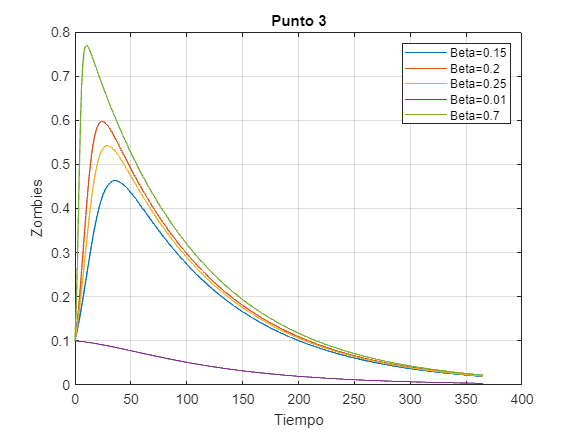

% CASO a

% defino tasa de trasnmisión
Beta3a = 0.15;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies3a = -Beta3a*S*I-Delta*S;
Tasa_IZombies3a = Beta3a*I*S-Gamma*I;
Tasa_RZombies3 = Gamma*I;
Tasa_VZombies3 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado3a = odeFunction([Tasa_SZombies3a Tasa_IZombies3a Tasa_RZombies3 Tasa_VZombies3],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo3a,Salida3a] = ode45(Funciones_estado3a,tspan,Ci_Zombies);

% CASO b

% defino tasa de trasnmisión
Beta3b = 0.25;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies3b = -Beta3b*S*I-Delta*S;
Tasa_IZombies3b = Beta3b*I*S-Gamma*I;
Tasa_RZombies3 = Gamma*I;
Tasa_VZombies3 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado3b = odeFunction([Tasa_SZombies3b Tasa_IZombies3b Tasa_RZombies3 Tasa_VZombies3],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo3b,Salida3b] = ode45(Funciones_estado3b,tspan,Ci_Zombies);

% CASO c

% defino tasa de trasnmisión
Beta3c = 0.20;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies3c = -Beta3c*S*I-Delta*S;
Tasa_IZombies3c = Beta3c*I*S-Gamma*I;
Tasa_RZombies3 = Gamma*I;
Tasa_VZombies3 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado3c = odeFunction([Tasa_SZombies3c Tasa_IZombies3c Tasa_RZombies3 Tasa_VZombies3],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo3c,Salida3c] = ode45(Funciones_estado3c,tspan,Ci_Zombies);

% CASO d

% defino tasa de trasnmisión
Beta3d = 0.01;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies3d = -Beta3d*S*I-Delta*S;
Tasa_IZombies3d = Beta3d*I*S-Gamma*I;
Tasa_RZombies3 = Gamma*I;
Tasa_VZombies3 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado3d = odeFunction([Tasa_SZombies3d Tasa_IZombies3d Tasa_RZombies3 Tasa_VZombies3],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo3d,Salida3d] = ode45(Funciones_estado3d,tspan,Ci_Zombies);

% CASO e

% defino tasa de trasnmisión
Beta3e = 0.7;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies3e = -Beta3e*S*I-Delta*S;
Tasa_IZombies3e = Beta3e*I*S-Gamma*I;
Tasa_RZombies3 = Gamma*I;
Tasa_VZombies3 = Delta*S;

% Vector de ci para resolver numericamente 
Ci3_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado3e = odeFunction([Tasa_SZombies3e Tasa_IZombies3e Tasa_RZombies3 Tasa_VZombies3],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo3e,Salida3e] = ode45(Funciones_estado3e,tspan,Ci_Zombies);

figure 
plot(tiempo3a,Salida3a (:,2))
hold on
plot(tiempo3b,Salida3b (:,2))
hold on 
plot(tiempo3c,Salida3c (:,2))
hold on 
plot(tiempo3d,Salida3d (:,2))
hold on 
plot(tiempo3e,Salida3e (:,2))
title('Punto 3')
xlabel('Tiempo')
ylabel('Zombies')
grid on
legend('Beta=0.15', 'Beta=0.2', 'Beta=0.25','Beta=0.01','Beta=0.7');

4.Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

*1y=0.15*

*2y=0.20*

*3y=0.25*

*4y=0.01*

*5y=0.7*

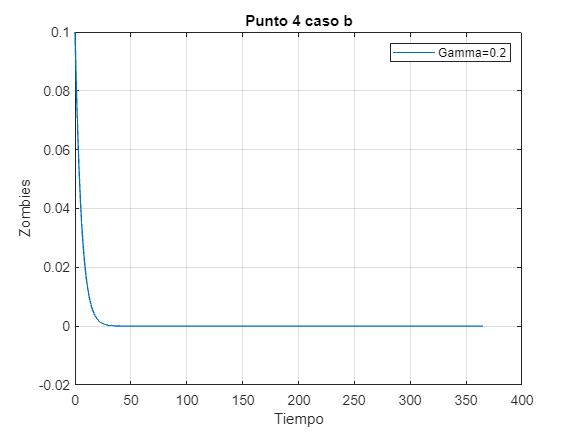

% CASO a

% defino tasa de trasnmisión
Gamma4a = 0.15;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies4 = -Beta*S*I-Delta*S;
Tasa_IZombies4a = Beta*I*S-Gamma4a*I;
Tasa_RZombies4a = Gamma4a*I;
Tasa_VZombies4 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado4a = odeFunction([Tasa_SZombies4 Tasa_IZombies4a Tasa_RZombies4a Tasa_VZombies4],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo4a,Salida4a] = ode45(Funciones_estado4a,tspan,Ci_Zombies);

% CASO b

% defino tasa de trasnmisión
Gamma4b = 0.25;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies4 = -Beta*S*I-Delta*S;
Tasa_IZombies4b = Beta*I*S-Gamma4b*I;
Tasa_RZombies4b = Gamma4b*I;
Tasa_VZombies4 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado4b = odeFunction([Tasa_SZombies4 Tasa_IZombies4b Tasa_RZombies4b Tasa_VZombies4],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo4b,Salida4b] = ode45(Funciones_estado4b,tspan,Ci_Zombies);

% CASO c

% defino tasa de trasnmisión
Gamma4c = 0.20;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies4 = -Beta*S*I-Delta*S;
Tasa_IZombies4c = Beta*I*S-Gamma4c*I;
Tasa_RZombies4c = Gamma4c*I;
Tasa_VZombies4 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado4c = odeFunction([Tasa_SZombies4 Tasa_IZombies4c Tasa_RZombies4c Tasa_VZombies4],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo4c,Salida4c] = ode45(Funciones_estado4c,tspan,Ci_Zombies);

% CASO d

% defino tasa de trasnmisión
Gamma4d = 0.01;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies4 = -Beta*S*I-Delta*S;
Tasa_IZombies4d = Beta*I*S-Gamma4d*I;
Tasa_RZombies4d = Gamma4d*I;
Tasa_VZombies4 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado4d = odeFunction([Tasa_SZombies4 Tasa_IZombies4d Tasa_RZombies4d Tasa_VZombies4],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo4d,Salida4d] = ode45(Funciones_estado4d,tspan,Ci_Zombies);
% CASO e

% defino tasa de trasnmisión
Gamma4e = 0.7;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies4 = -Beta*S*I-Delta*S;
Tasa_IZombies4e = Beta*I*S-Gamma4e*I;
Tasa_RZombies4e = Gamma4e*I;
Tasa_VZombies4 = Delta*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado4e = odeFunction([Tasa_SZombies4 Tasa_IZombies4e Tasa_RZombies4e Tasa_VZombies4],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo4e,Salida4e] = ode45(Funciones_estado4e,tspan,Ci_Zombies);

figure 
plot(tiempo4b,Salida4b (:,2))

title('Punto 4 caso b')
xlabel('Tiempo')
ylabel('Zombies')
grid on
legend('Gamma=0.2')

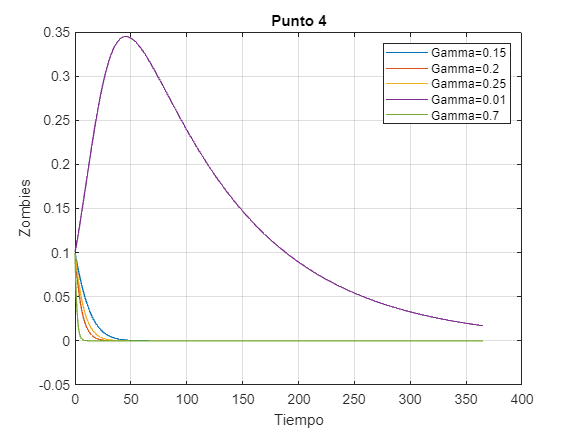


figure 
plot(tiempo4a,Salida4a (:,2))
hold on
plot(tiempo4b,Salida4b (:,2))
hold on 
plot(tiempo4c,Salida4c (:,2))
hold on 
plot(tiempo4d,Salida4d (:,2))
hold on 
plot(tiempo4e,Salida4e (:,2))
title('Punto 4')
xlabel('Tiempo')
ylabel('Zombies')
grid on
legend('Gamma=0.15', 'Gamma=0.2', 'Gamma=0.25','Gamma=0.01','Gamma=0.7')

5.Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

*1oa = 0.15*

*2ob = 0.20*

*3oc = 0*

*4od = 0.7*

*5oe = 0.05*

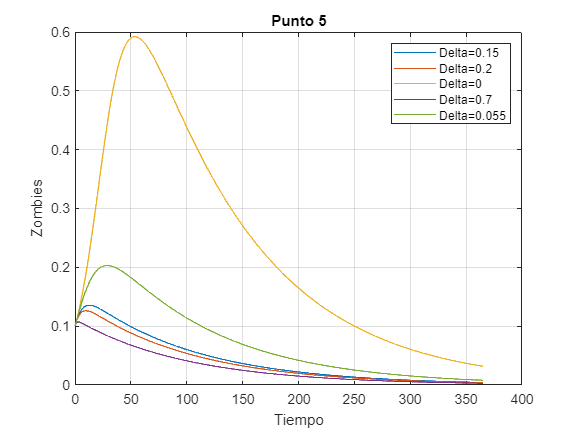

% CASO a

% defino tasa de trasnmisión
Delta5a = 0.15;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies5a = -Beta*S*I-Delta5a*S;
Tasa_IZombies5 = Beta*I*S-Gamma*I;
Tasa_RZombies5 = Gamma*I;
Tasa_VZombies5a = Delta5a*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado5a = odeFunction([Tasa_SZombies5a Tasa_IZombies5 Tasa_RZombies5 Tasa_VZombies5a],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo5a,Salida5a] = ode45(Funciones_estado5a,tspan,Ci_Zombies);

% CASO b

% defino tasa de trasnmisión
Delta5b = 0.20;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies5b = -Beta*S*I-Delta5b*S;
Tasa_IZombies5 = Beta*I*S-Gamma*I;
Tasa_RZombies5 = Gamma*I;
Tasa_VZombies5b = Delta5b*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado5b = odeFunction([Tasa_SZombies5b Tasa_IZombies5 Tasa_RZombies5 Tasa_VZombies5b],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo5b,Salida5b] = ode45(Funciones_estado5b,tspan,Ci_Zombies);


% CASO c

% defino tasa de trasnmisión
Delta5c = 0;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies5c = -Beta*S*I-Delta5c*S;
Tasa_IZombies5 = Beta*I*S-Gamma*I;
Tasa_RZombies5 = Gamma*I;
Tasa_VZombies5c = Delta5c*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado5c = odeFunction([Tasa_SZombies5c Tasa_IZombies5 Tasa_RZombies5 Tasa_VZombies5c],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo5c,Salida5c] = ode45(Funciones_estado5c,tspan,Ci_Zombies);

% CASO d

% defino tasa de trasnmisión
Delta5d = 0.7;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies5d = -Beta*S*I-Delta5d*S;
Tasa_IZombies5 = Beta*I*S-Gamma*I;
Tasa_RZombies5 = Gamma*I;
Tasa_VZombies5d = Delta5d*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado5d = odeFunction([Tasa_SZombies5d Tasa_IZombies5 Tasa_RZombies5 Tasa_VZombies5d],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo5d,Salida5d] = ode45(Funciones_estado5d,tspan,Ci_Zombies);


% CASO e

% defino tasa de trasnmisión
Delta5e = 0.055;

% defino las ecuaciones de estado para a invasión zombie
Tasa_SZombies5e = -Beta*S*I-Delta5e*S;
Tasa_IZombies5 = Beta*I*S-Gamma*I;
Tasa_RZombies5 = Gamma*I;
Tasa_VZombies5e = Delta5e*S;

% Vector de ci para resolver numericamente 
Ci_Zombies = [Ci_SZ Ci_IZ Ci_RZ Ci_VZ];
% Usamos el comando ODE445 para resolver
Funciones_estado5e = odeFunction([Tasa_SZombies5e Tasa_IZombies5 Tasa_RZombies5 Tasa_VZombies5e],[S  I R V]);
% Resolver usando comando ODE 45
[tiempo5e,Salida5e] = ode45(Funciones_estado5e,tspan,Ci_Zombies);

%graficamos soluciones
figure 
plot(tiempo5a,Salida5a (:,2))
hold on
plot(tiempo5b,Salida5b (:,2))
hold on 
plot(tiempo5c,Salida5c (:,2))
hold on 
plot(tiempo5d,Salida5d (:,2))
hold on 
plot(tiempo5e,Salida5e (:,2))
title('Punto 5')
xlabel('Tiempo')
ylabel('Zombies')
grid on
legend('Delta=0.15', 'Delta=0.2', 'Delta=0','Delta=0.7','Delta=0.055');

#### **Discusión y conclusiones**

**Grafica invasión zombie**

En esta grafica pordemos observar que la población de personas suceptibles disminye con el tiempo mientras que los recuperados aumentan gradualmente, al igual que los vacunados, casi con la misma proporción.  Por otro lado, la población zombie inicialmente aumenta alcanzando su punto maximoaproximadamente en el punto (50,0.35), luego disminuye y finalmente el sistema se estabiliza.

Este comportamiento se debe a las derivadas de estas poblaciones. Los susceptibles disminuyen debido a que su derivada es negativa esta es la pobalción que aún no ha sido infectada pero esta en riesgo, su dinamica se relaciona con la tasa de infección y la tasa de vacunación del sistema en función del tiempo, cuando la tasa de infección es alta y la mayoria de la población no está vacunada, la población de suceptibles tiende a disminuir rapidamente ya que pasan a la categoria de infectados, pero cuando se implementan las medidas de control, la población de suceptibles aumenta porque mas personas estan protegidas contra la onfeccion y son menos suceptibles a contraerla, mientras que los recuperados y los vacunados aumentan porque sus derivadas son positivas, esta categoria esta compuesta por las personas que han adquirido inmunidad contra la enfermedad, en este caso son inmunes a volverse zombies infectados, normalmente esta categoria aumenta con el tiempo y esto ayuda a reducir la cantidad de infectados ya que es mas dificil que se propague la invasión. La población de infectados sube y luego baja debido a la dinamica de infección y recuperación en el sistema, la derivada de la población de infectados representa la tasa de cambio de infectados en función del tiempo, cuando es positiva significa que los casos de infectados estan en aumento y cuando es nefativa significa que esta disminuyendo, es decir, que las personas se estan recuperandomas rapido que las nuevas infecciones. El estado de equilibrio se alcanza cuando la mayoria de las personas están recuperadas o vacunadas y no se propaga la infección.

**Gráfica de pobalción vacunada al 54%**

En la grafica se puede ver como la población infectada aumenta rapidamente en el tiempo pero cuando llega a el tope de 0.15 empieza a disminuir.

Para que el pico de infectados llegue al 15% de la poblacion se ha calculado que al menos el 54% de la población suceptible debe ser vacunada antes de que comience el brote para que no se sobrepase el 15% de infectados, la vacunación ayuda a reducir la propagación de la enfermedad al aumentar la porporción de personas inmunes en la población, lo que limita las personas que pueden contagiarse en el brote.

**Gráfica del punto 2**

Aumentar la población inicial de infectados imolicaria que hay mas personas con la enfermedad desde el principio lo que tiene varias consecuencias en el modelo, al inicio se puede ver mayor porpagación inicial debido a que hay mayor posibilidades de propagación zombie, porque hay mas zombies que personas sanas, tambien se puede observar picos de infectados temprano, es decir, el punto maximo de infectados se alcanza mas rapido cuando las condiciones iniciales de estos son mayores, ya que hay mas zombies que estan buscando infectar a personas normales y las vacunas no son suficientes, tambien la vacunación tiene menor impacto, si se inicia después de que haya un números de infectados grande, puede ser menos efectiva en la reducción de la invasión porque una gran parte de la población ya estaria infectada. 

Se puede decir entones que al aumentar las condiciones iniciales de los infectados en el modelo SIRV cambia la dinámica de la invasión, haciendo que la propagación sea mas rápida y el pico de infectados se alcance en menor tiempo, por esto el control de la invasión es mas desafiante y es más dificil aumentar el número de recuperados.

**Gráfica del punto 3**

Al aumentar beta se ven algunos cambios en la dinamica del modelo SIRV como el aumento en la tasa de la propagación y por ende el crecimiento exponencial de los infectados al ser mayor la tasa de infección más personas se infectarán en menos tiempo y la baja cantidad de población suceptible (que pasa a estar infectada). Tambien se puede ver que entre mas grande es beta el pico de infectados se alcanza más rapido, todo esto tiene como consecuencia una presión mayor en el proceso de vacunación para alcanzar la inmunidad colectiva y controlar la invasión zombie. En este caso la gráfica nos permite evidenciar que a una tasa de transmisión del 1% la pandemia ya no cuenta con un pico de infección y la gráfica se estabiliza rápidamente, por otro lado cuando beta = 0.15 tambien tiene un pico no tan alto ni acelerado en el tiempo, pero igual sigue siendo un punto critico. 

**Gráfica del punto 4**

Gama influye la tasa de recuperados por ende si se aumenta la tasa de recuperados se puede ver una reducción en la duración de la enfermedad porque las personas infectadas se  recuperan mas rápido ya que tienen una relacion inversa, por lo que hay menos infectados en un momento dado, esto se traduce en un pico de infectados zombie más bajo, por la combinación de una tasa de infección constante y una tasa de recuperados alta conduce a picos de infectados cada vez mas bajos, si se sigue aumentando gamma se puede decir que se llega al fin de la invasión zombie y la gráfica muestra que para evitar una  invasión la tasa de población recuperada debe de ser del 7% con un excelente sistema de vacunación y un plan de salud y control, tambien podemos ver que con 1% de recuperados la invasión se dispara considerablemente frente a los otros valores.

**Gráfica del punto 5**

El parámetro delta, representa la fluctuación en la tasa de vacunación, es un factor crítico en la dinámica del modelo, porque tiene una relación inversa entre la tasa de vacunación y el número de personas infectadas, así como con el pico de la enfermedad. A medida que aumenta la cantidad de personas vacunadas, el pico de infectados disminuye.  Además, Se ha identificado que una tasa mínima de población vacunada del 5.5% es necesaria para que el pico de infectados alcance el 0.2, es muy importante alcanzar este humbral de vacunación para que la población pueda estar un poco mas tranquila respecto a la propagación de la invasión zombie, por esto, el parámetro delta, que representa la tasa de vacunación en el modelo SIRV, es importante para entender cómo las estrategias de vacunación pueden influir en la propagación de la invasión y en la reducción del pico de infectados. 